# Median Filter a Noisy Image

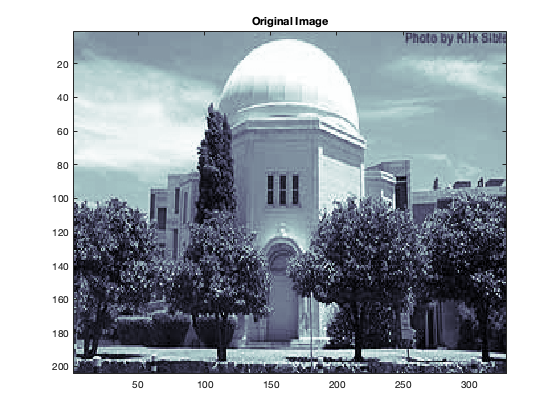

obj = importdata('forclass.mat');
img_original = obj;
y = size(obj,1); % image height 
x = size(obj,2); % image width

% Add noise to the image 
obj = obj + rand(size(obj))*100;

% Create 3x3 median filter 
n = 7;  % odd #'s only for the center 
m = (n-1)/2; % the outer edge size
objPad = [flip(obj(:,1:m),2), obj, flip(obj(:,end-(m-1):end),2)]; % Pad the coloums
objPad = [flip(objPad(1:m,:),1); objPad; flip(objPad(end-(m-1):end,:),1)]; % Pad the rows

% initialize empty matrix
res = zeros(y,x);

% Double loop for calculation
for ii = 1:y
    for jj = 1:x
        res(ii,jj) = median(reshape(objPad(ii:ii+(n-1),jj:jj+(n-1)),1,[]));
    end
end

% Plot Image
figure()
imagesc(img_original)
colormap bone
title('Original Image')

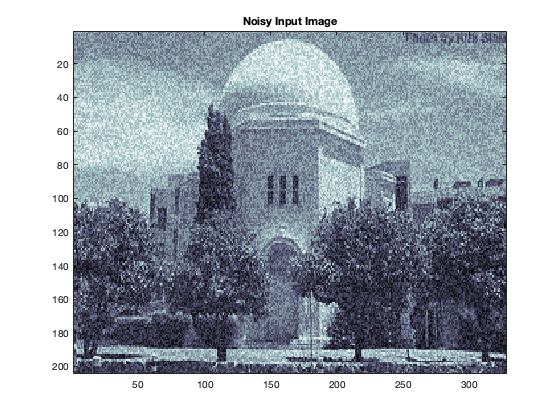


figure()
imagesc(obj)
colormap bone
title('Noisy Input Image')

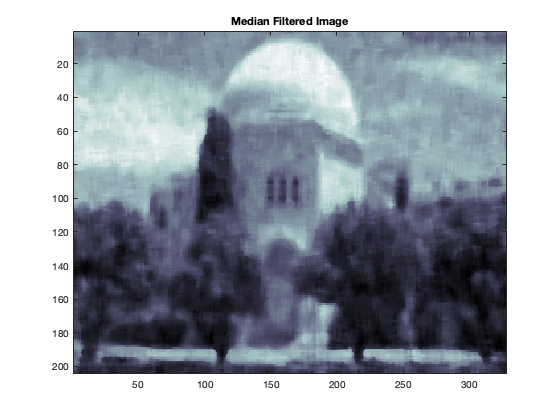


figure()
imagesc(res)
colormap bone
title('Median Filtered Image')